# Lab3

dt = 0.01;
t = -10 : dt : 10;

## Esercizio 1 (i)

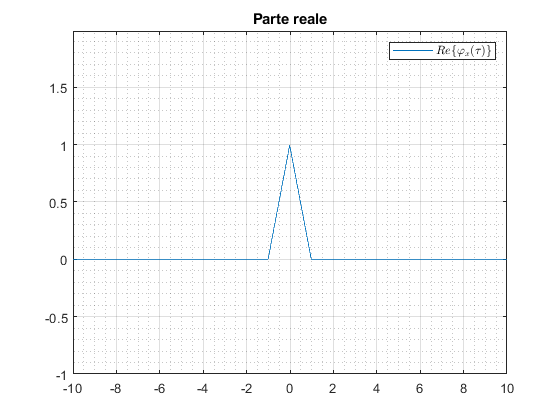

phiX = autoCorrelazione(t, rect(t));
rappresentaUnSegnale(phiX(1, :), phiX(2, :), '\varphi_{x}(\tau)');

## Esercizio 1 (ii)

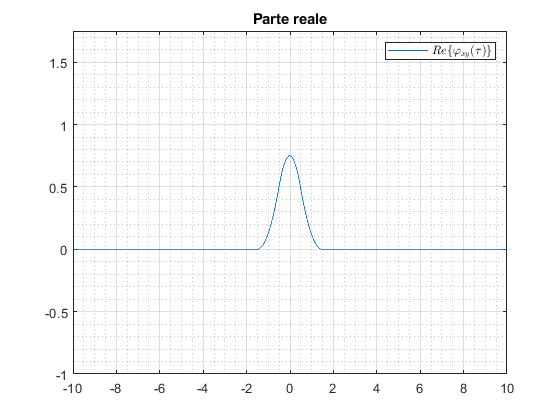

phiXY = crossCorrelazione(t, rect(t), tri(t));
rappresentaUnSegnale(phiXY(1, :), phiXY(2, :), '\varphi_{xy}(\tau)');

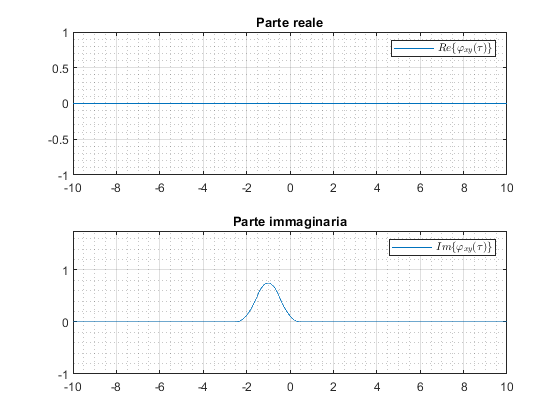

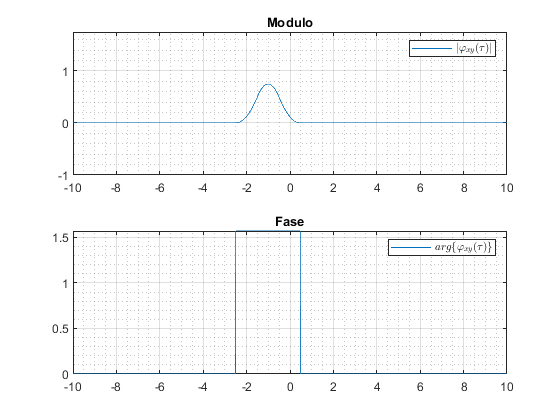

phiXY = crossCorrelazione(t, rect(t), 1i * tri(t + 1));
rappresentaUnSegnale(phiXY(1, :), phiXY(2, :), '\varphi_{xy}(\tau)');

## Esercizio 1 (iii)

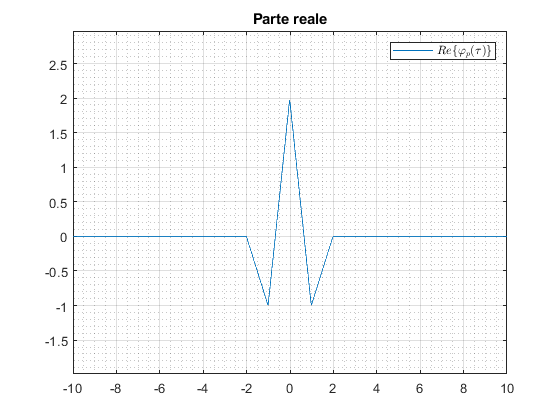

phiP = autoCorrelazione(t, rect(t - 1 / 2) - rect(t - 3 / 2));
rappresentaUnSegnale(phiP(1, :), phiP(2, :), '\varphi_{p}(\tau)');

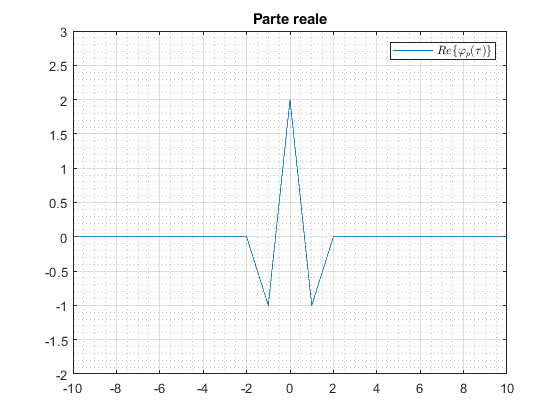

phiPAnalitico = 2 * tri(t) - tri(t + 1) - tri(t - 1);
rappresentaUnSegnale(t, phiPAnalitico, '\varphi_{p}(\tau)');

## Esercizio 2 (i)

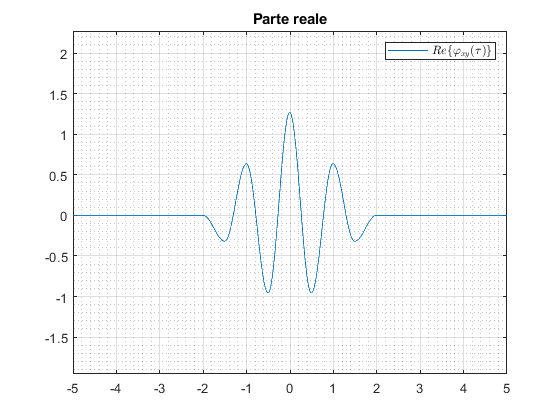

x = zeros(size(t));
for k = -length(x):length(x)
	x = x + rect(t - 1 / 2 - 2  * k) - rect(t - 3 / 2 - 2 * k);
end
phiXY = crossCorrelazioneCircolare(t, x, sin(pi * t), 2);
figure;
rappresentaUnSegnale(phiXY(1,:), phiXY(2,:), '\varphi_{xy}(\tau)');

## Esercizio 3 (i)

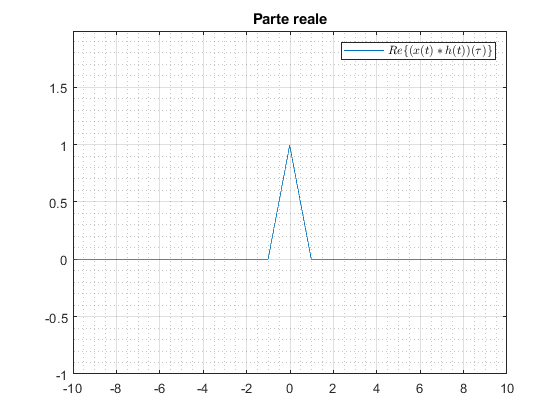

convXH = convoluzione(t, rect(t), rect(t));
rappresentaUnSegnale(convXH(1,:), convXH(2,:), '(x(t)*h(t))(\tau)');

## Esercizio 3 (ii)

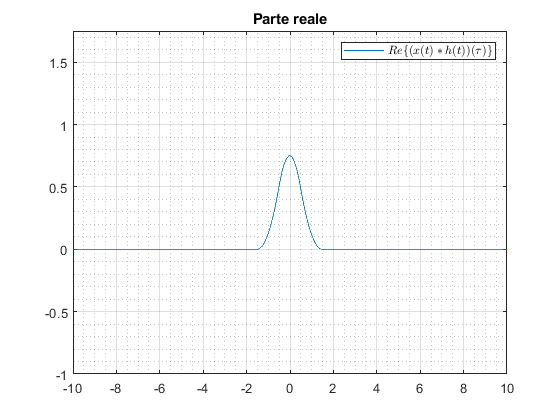

convXH = convoluzione(t, rect(t), tri(t));
rappresentaUnSegnale(convXH(1,:), convXH(2,:), '(x(t)*h(t))(\tau)');

## Esercizio 3 (iii)

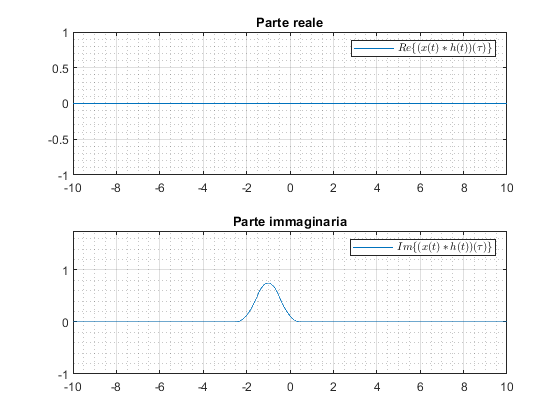

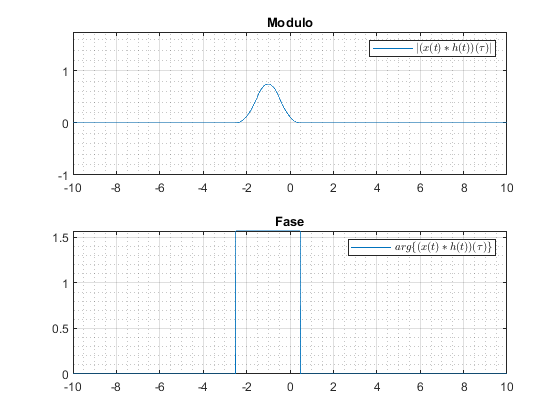

convXH = convoluzione(t, rect(t), 1i * tri(t + 1));
rappresentaUnSegnale(convXH(1,:), convXH(2,:), '(x(t)*h(t))(\tau)');

## Esercizio 3 (iv)

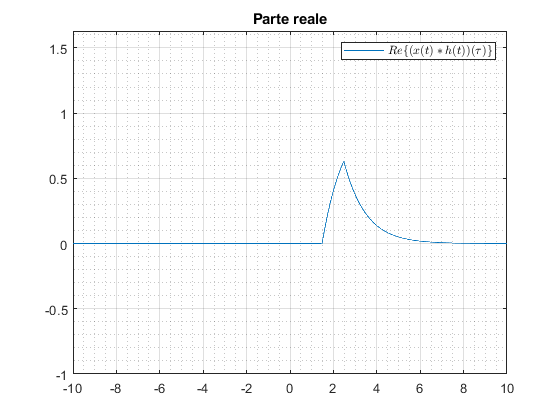

convXH = convoluzione(t, rect(t - 2), exp(-t) .* gradino(t));
rappresentaUnSegnale(convXH(1,:), convXH(2,:), '(x(t)*h(t))(\tau)');

## Esercizio 3 (v)

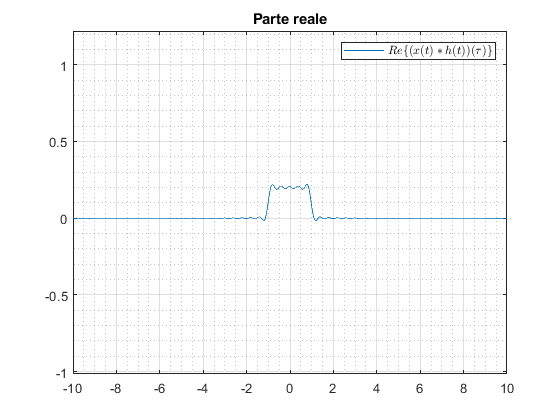

convXH = convoluzione(t, rect(t / 2), sinc(5 * t));
rappresentaUnSegnale(convXH(1,:), convXH(2,:), '(x(t)*h(t))(\tau)');